clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


## Same real uncertainty for every input


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureRealUncertainties(param,0,{[-1,1]});

Evaluation of design procedure for real uncertainties 
Q is positive definite


ans =     0.0019    0.0020    0.0020    0.0020    0.1519    0.1531    0.1531    0.1533    4.7172    4.7529    4.7813    4.8001


Eigenvalues of the decoupled systems are all negative 


ans =   -93.6770   -3.9815   -0.0185  -90.9897   -4.0192   -0.0187  -90.8536   -3.9815   -0.0187  -95.2199   -3.9817   -0.0183


Eigenvalues of the coupled systems are all negative 


ans =  -161.8924 -207.7458 -215.4957 -223.3732   -4.0198   -3.9820   -3.9821   -3.9822   -0.0183   -0.0185   -0.0187   -0.0187


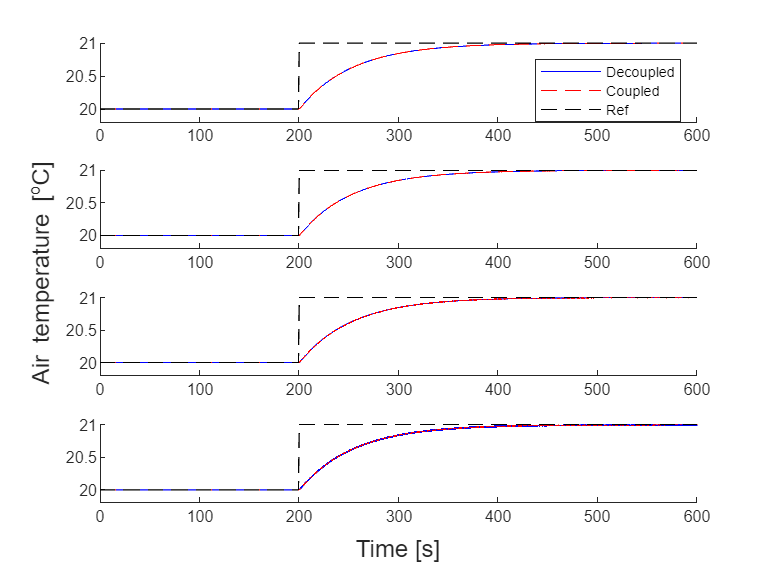

util.SimulateLinearStep(param, "Examination_Real_Uncertainties_Identical",1);

## Individual real uncertainty for every input


$$\Delta= 
\left[\matrix{\delta_1 & 0 & 0 & 0 \cr 0 & \delta_2 & 0 & 0 \cr
0 & 0 & \delta_3 & 0 \cr 0 & 0 & 0 & \delta_4}\right], \qquad \delta_i \in [-1,1], \quad i=1,2,3,4$$


param = control.DesignProcedureRealUncertainties(param,0,{[-1,1],[-1,1],[-1,1],[-1,1]});

Evaluation of design procedure for real uncertainties 
Q is positive definite


ans =     0.0023    0.0024    0.0025    0.0026    0.1258    0.1265    0.1271    0.1273   10.6154   10.8612   10.8863   10.8922


Eigenvalues of the decoupled systems are all negative 


ans =    -4.0059   -0.0311   -0.0000   -4.0442   -0.0312   -0.0000   -4.0059   -0.0311   -0.0000   -4.0058   -0.0311   -0.0000


Eigenvalues of the coupled systems are all negative 


ans =    -4.0442   -4.0059   -4.0059   -4.0058   -0.0311   -0.0312   -0.0311   -0.0311   -0.0000   -0.0000   -0.0000   -0.0000


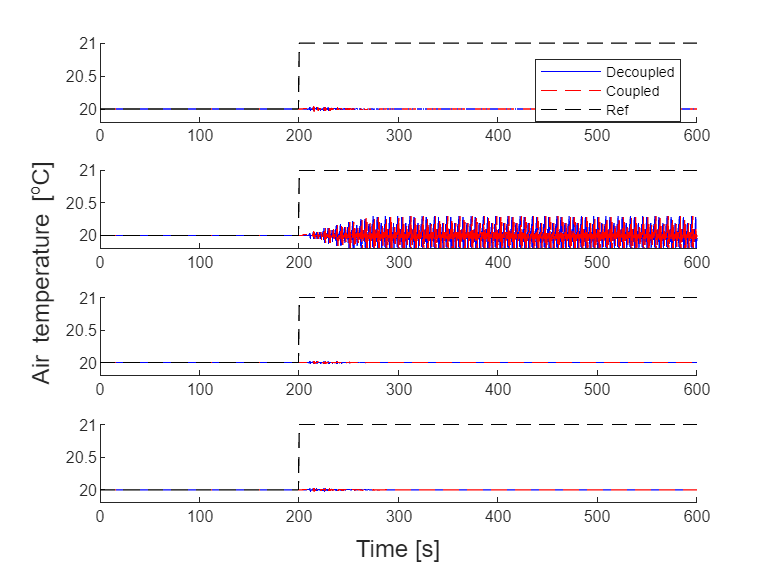

util.SimulateLinearStep(param, "Examination_Real_Uncertainties_Individual",1);